# 二阶系统阶跃响应的参数

不同参数下的二阶系统的主要参数计算和阶跃响应：

Omega_n=4;
Xi=0.35;
Omega_d=sqrt(1-Xi*2)*Omega_n;
Sigma=Xi*Omega_n;
Beta=atan(Xi);
sys=tf(Omega_n^2,[1 2*Xi*Omega_n Omega_n^2]);
if Xi<1 && Xi>0
    params=twoJ(Xi,Omega_n);
    display(params)
end

params = 1×5 table
      t_r        t_p      SigmaPercent    t_s1     t_s2 
    _______    _______    ____________    ____    ______

    0.74858    0.83843      0.30919       2.5     3.1429


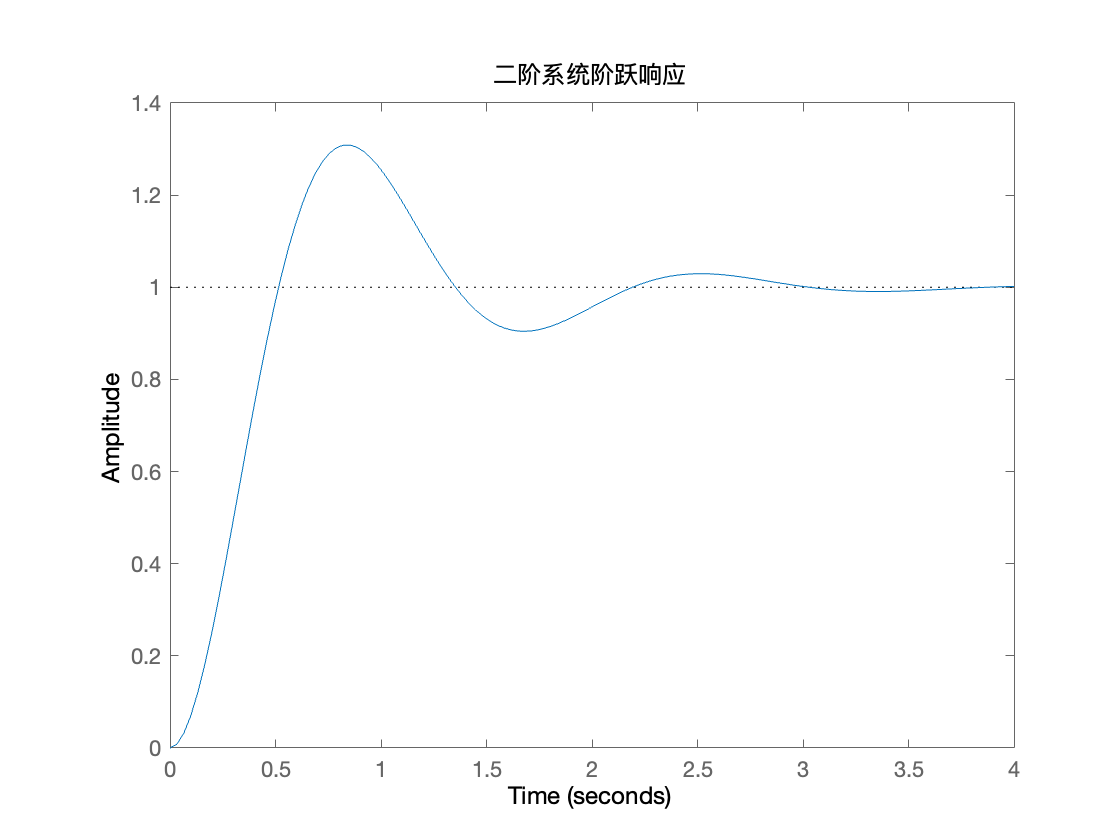

figure();
stepplot(sys);
title('二阶系统阶跃响应');

## 二阶系统各个性能指标与阻尼比的关系

自然频率为1的情况下，考察不同阻尼比下二阶系统的性能指标。

- 上升时间和峰值时间反应系统的快速性，阻尼比越小，快速性越好

- 超调量和调节时间反映准确性，阻尼比越大，准确性越好

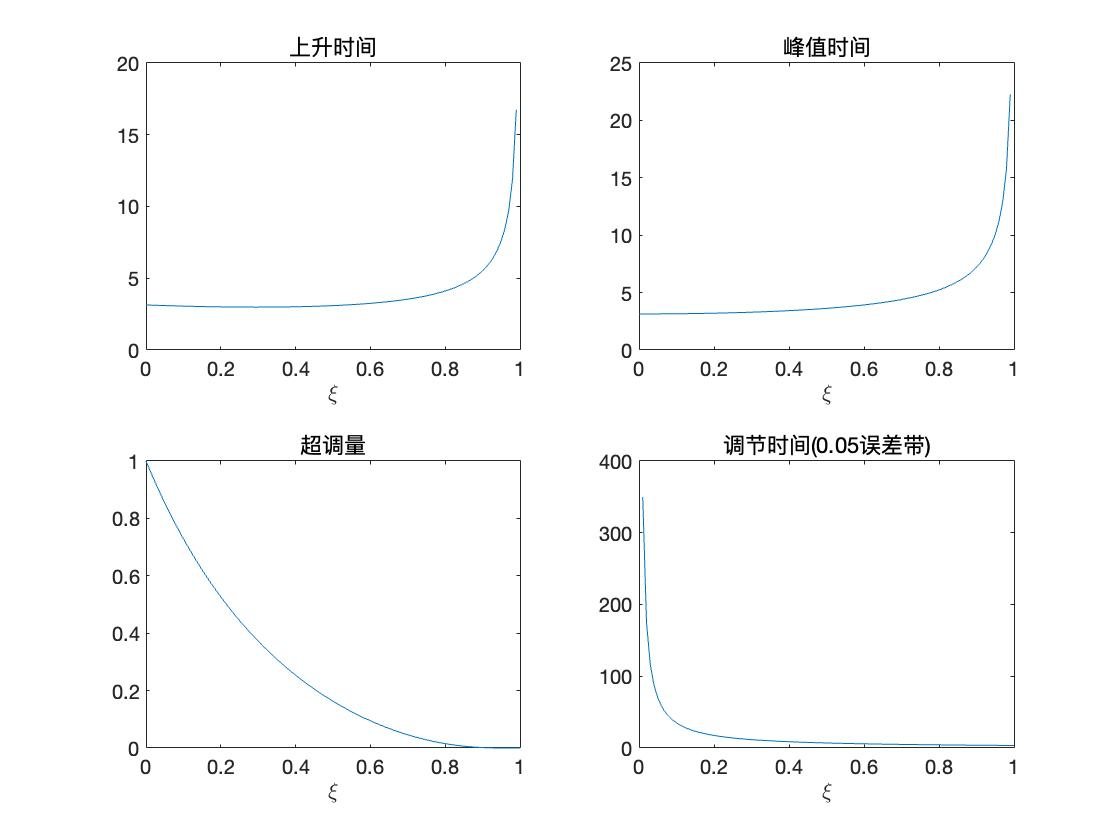

Xi=0:0.01:1;
Xi=Xi';
Omega_n=ones(size(Xi));
T=twoJ(Xi,Omega_n);
figure();hold on
subplot(2,2,1);
plot(Xi,T.t_r);
xlabel('$\xi$',"Interpreter","latex");
title("上升时间");

subplot(2,2,2);
plot(Xi,T.t_p);
xlabel('$\xi$',"Interpreter","latex");
title("峰值时间");

subplot(2,2,3);
plot(Xi,T.SigmaPercent);
xlabel('$\xi$',"Interpreter","latex");
title("超调量");

subplot(2,2,4);
plot(Xi,T.t_s1);
xlabel('$\xi$',"Interpreter","latex");
title("调节时间(0.05误差带)");